tabledata=readtable("data.xlsx");

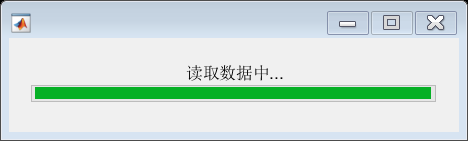

T0=floor(datenum(tabledata{1,1})*1440);
Te=floor(datenum(tabledata{end,1})*1440);
T_l=T0;
i_l=1;
data_s=zeros(Te-T0,15);
bar = waitbar(0,'读取数据中...');

len = size(tabledata,1);
for i=1:len
    if floor(datenum(tabledata{i,1})*1440)>T_l
        tmp=mean(tabledata{i_l:(i-1),2:end});
        i_l=i;
        T_l=floor(datenum(tabledata{i,1})*1440);
        data_s(T_l-T0,:)=tmp;
        waitbar(i/len,bar)
    end
end

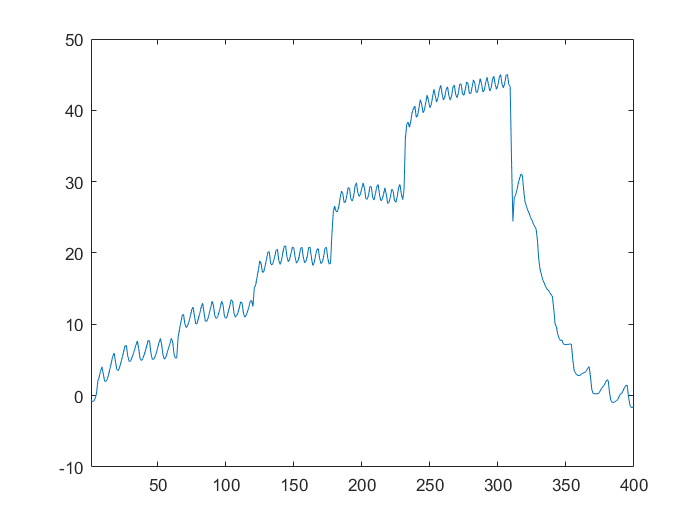

L=data_s(:,1);
t=1:length(L);
plot(t,L);
xlim([1,400]);

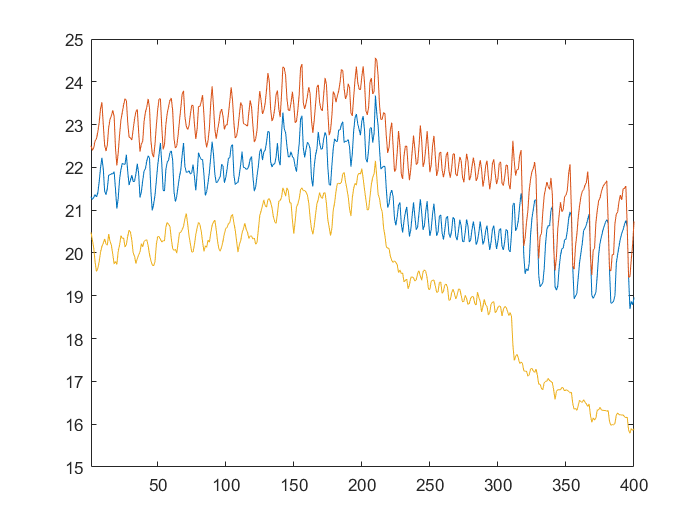

figure;
plot(t,data_s(:,[13,15,7]));
xlim([1,400]);

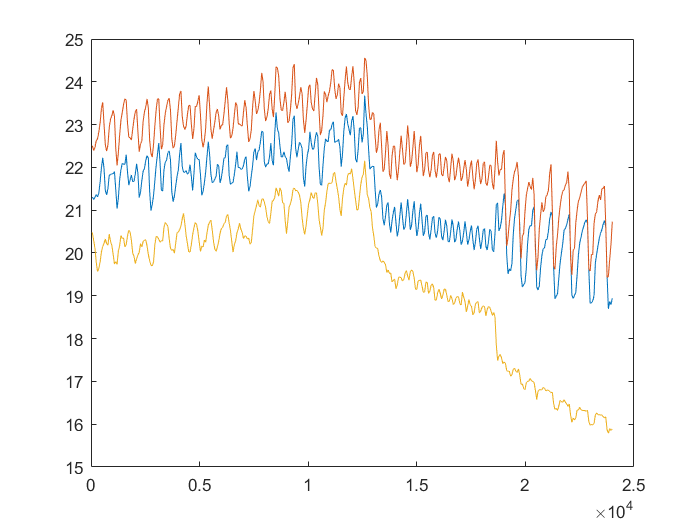

speed=[ones(64,1)*3000;ones(55,1)*6000;ones(57,1)*9000;ones(54,1)*12000;ones(78,1)*15000;zeros(92,1)];
T_in=data_s(1:length(speed),[13,15,7]);
time=(1:length(speed))'*60;
csvwrite("DT_input",[time,speed,T_in]);
figure
plot(time,T_in);

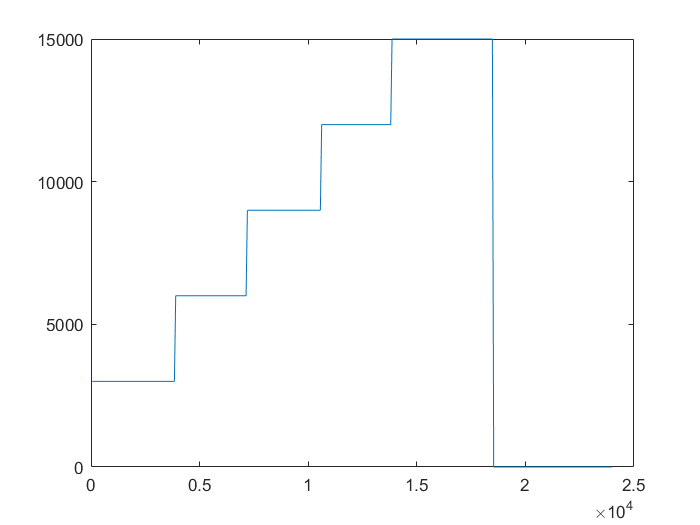

figure;
plot(time,speed);